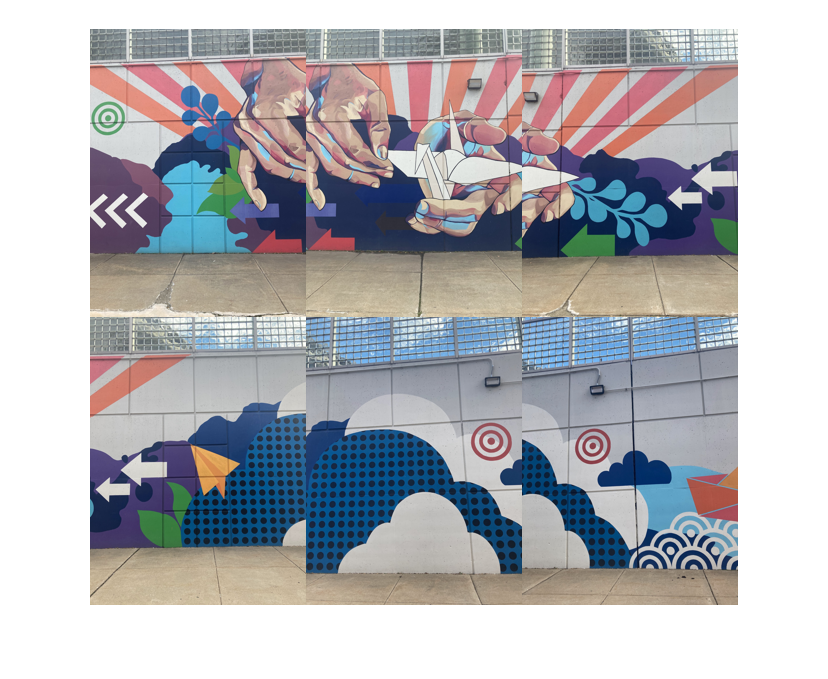

clear all
clc
% Load images.
pan_val = "mural2_15";

if pan_val == "mural1"
    cd 'C:\Users\divg2\OneDrive\Desktop\Desktop\Coursework\EE5559\latino_center'
    mural_scene = imageDatastore(["img1.jpeg","img2.jpeg","img3.jpeg","img4.jpeg","img6.jpeg","img8.jpeg","img9.jpeg","Img10.jpeg"]);
elseif pan_val == "mural2_15"
    cd 'C:\Users\divg2\OneDrive\Desktop\Desktop\Coursework\EE5559\mural_15'
    mural_scene = imageDatastore(["img1.jpg","img2.jpg","img3.jpg","img4.jpg","img5.jpg","img6.jpg"]);
elseif pan_val == "mural2_50"
    cd 'C:\Users\divg2\OneDrive\Desktop\Desktop\Coursework\EE5559\mural_50'
    mural_scene = imageDatastore(["img1.jpg","img2.jpg","img3.jpg","img4.jpg","img5.jpg","img6.jpg","img7.jpg"]);
else
    cd 'C:\Users\divg2\OneDrive\Desktop\Desktop\Coursework\EE5559\brick_wall'
    mural_scene = imageDatastore(["img2.jpeg","img3.jpeg","img4.jpeg","img6.jpeg"]);
end

% Display images to be stitched.
montage(mural_scene.Files);

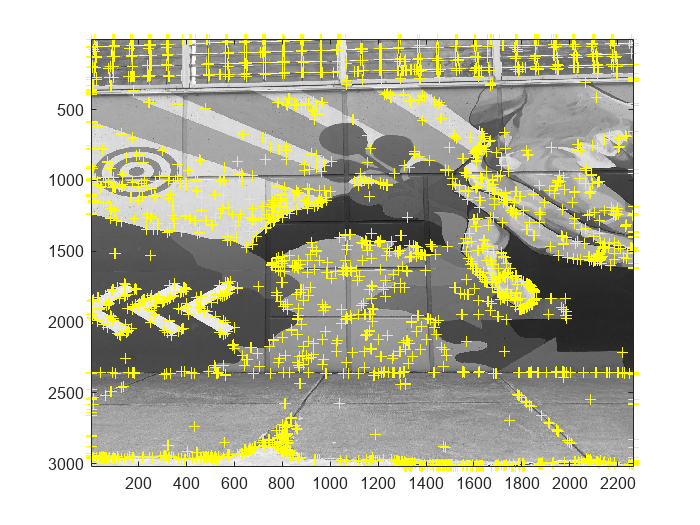

% Read the first image from the image set.
I = readimage(mural_scene,1);
max_pt = 2500;
window = [4 4];
% Initialize features for I(1)
grayImage = im2gray(I);
[y,x] = harris(grayImage, max_pt,'tile', window,'disp');

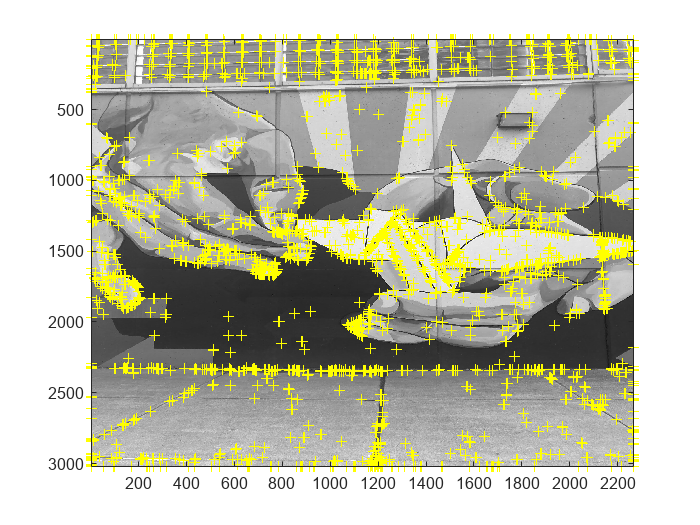

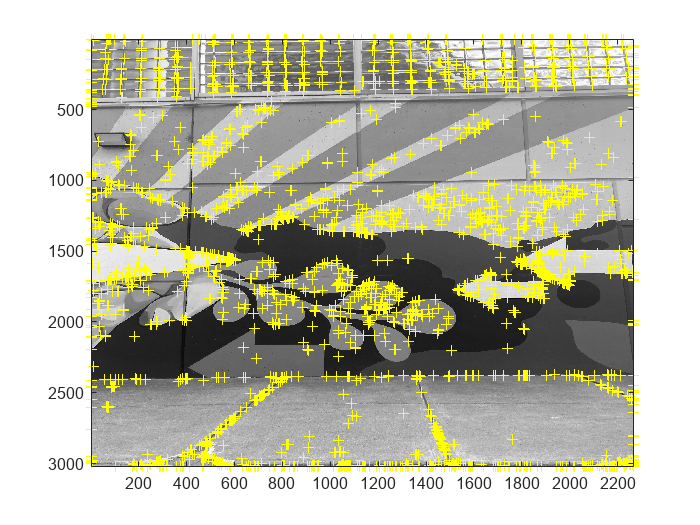

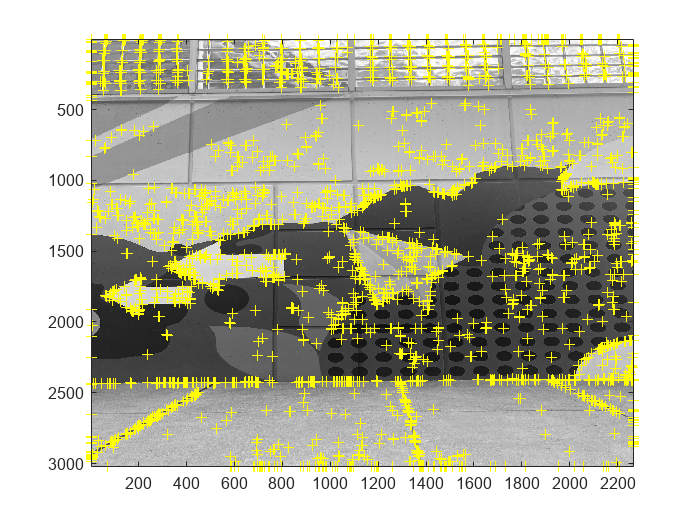

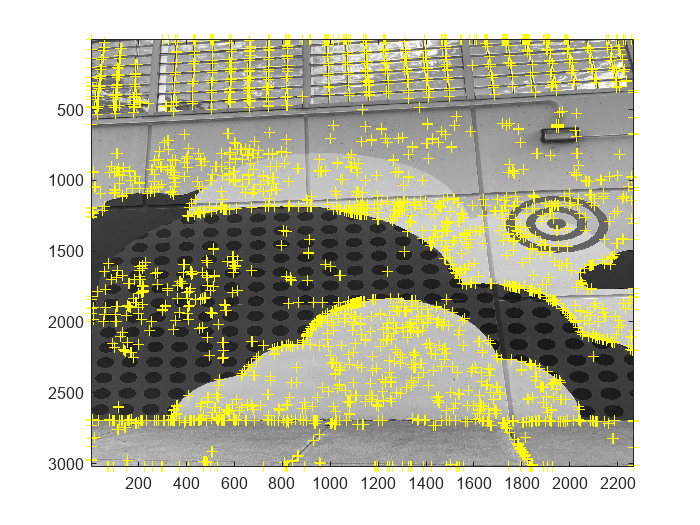

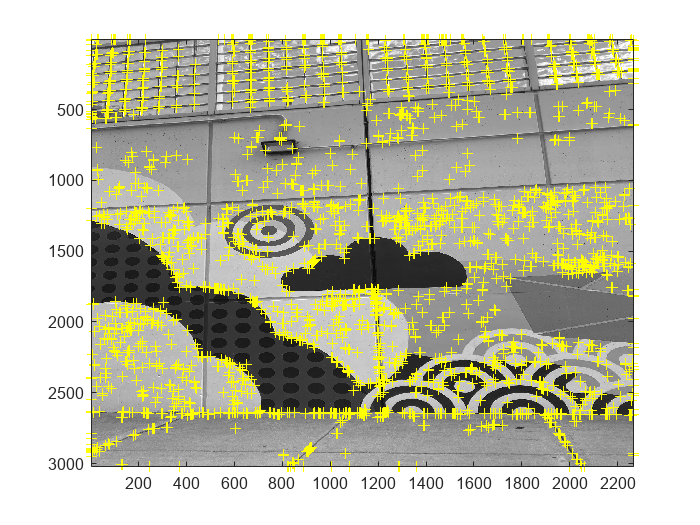

points = cornerPoints([x, y]);
[features, points] = extractFeatures(grayImage,points);

numImages = numel(mural_scene.Files);
tforms(numImages) = affinetform2d;

% Initialize variable to hold image sizes.
imageSize = zeros(numImages,2);

% Iterate over remaining image pairs
for n = 2:numImages
    % Store points and features for I(n-1).
    pointsPrevious = points;
    featuresPrevious = features;
        
    % Read I(n).
    I = readimage(mural_scene, n);
    
    % Convert image to grayscale.
    grayImage = im2gray(I);    
    
    % Save image size.
    imageSize(n,:) = size(grayImage);
    
    % Detect and extract SURF features for I(n).
    [y,x,m] = harris(grayImage,max_pt,'tile',window,'disp');
    points = cornerPoints([x, y]);
    [features, points] = extractFeatures(grayImage, points);
  
    % Find correspondences between I(n) and I(n-1).
    indexPairs = matchFeatures(features, featuresPrevious, 'Unique', true);
       
    matchedPoints = points(indexPairs(:,1), :);
    matchedPointsPrev = pointsPrevious(indexPairs(:,2), :);        
    
    % Estimate the transformation between I(n) and I(n-1).
    tforms(n) = estgeotform2d(matchedPoints, matchedPointsPrev,...
        "affine", 'Confidence', 80, 'MaxNumTrials', 2000);
    
    % Compute T(1) * T(2) * ... * T(n-1) * T(n).
    tforms(n).T = tforms(n-1).T * tforms(n).T; 
end

% Compute the output limits for each transformation.
for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);    
end

avgXLim = mean(xlim, 2);
[~,idx] = sort(avgXLim);
centerIdx = floor((numel(tforms)+1)/2);
centerImageIdx = idx(centerIdx);

Tinv = invert(tforms(centerImageIdx));

for i = 1:numel(tforms)    
    tforms(i).T = Tinv.T * tforms(i).T;
end

for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);
end

maxImageSize = max(imageSize);

% Find the minimum and maximum output limits. 
xMin = min([1; xlim(:)]);
xMax = max([maxImageSize(2); xlim(:)]);

yMin = min([1; ylim(:)]);
yMax = max([maxImageSize(1); ylim(:)]);

% Width and height of panorama.
width  = round(xMax - xMin);
height = round(yMax - yMin);

% Initialize the "empty" panorama.
panorama = zeros([height width 3], 'like', I);

blender = vision.AlphaBlender('Operation', 'Binary mask', ...
    'MaskSource', 'Input port');  

% Create a 2-D spatial reference object defining the size of the panorama.
xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width], xLimits, yLimits);

% Create the panorama.
for i = 1:numImages
    
    I = readimage(mural_scene, i);   
   
    % Transform I into the panorama.
    warpedImage = imwarp(I, tforms(i), 'OutputView', panoramaView);
                  
    % Generate a binary mask.    
    mask = imwarp(true(size(I,1),size(I,2)), tforms(i), 'OutputView', panoramaView);
    
    % Overlay the warpedImage onto the panorama.
    panorama = step(blender, panorama, warpedImage, mask);
end

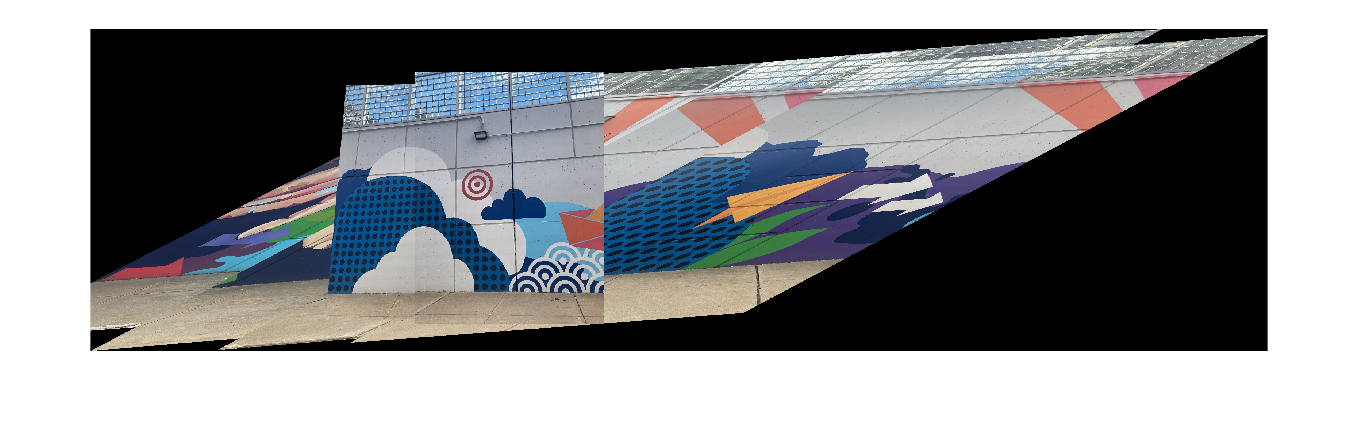

figure
imshow(panorama)